# Teorema fundamental del cálculo 

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

 Una conexión profunda entre el cálculo diferencial e integral es la relación entre [funciones de acumulación](matlab:open('./Riemann.mlx')) y [funciones derivadas](https://www.mathworks.com/matlabcentral/fileexchange/99249-calculus-derivatives). 

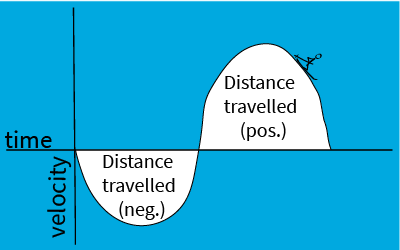

El área geométrica bajo una curva corresponde a la acumulación total del producto de los valores seguidos a lo largo de cada eje. En esta imagen, la velocidad multiplicada por el tiempo es distancia. 

** Antes de comenzar: **

Este live script está diseñado para usarse con el código oculto. En la pestaña **View** de la barra de herramientas de MATLAB, en la sección** View**, selecciona **Hide Code**. Alternativamente, selecciona **Hide Code **usando el ícono   en la parte superior derecha del panel del Live Editor. 

 Aunque el código está oculto, cierta interactividad requiere familiaridad con MATLAB. Si necesita más instrucción, considera tomar el [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea gratuito de 2 horas que enseña los conceptos básicos de MATLAB. 

 Para una experiencia óptima, sigue las instrucciones y pasos en la secuencia indicada. Pasa a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan fuera de orden. 

## Practique integrales definidas aleatorias 

  ** Consejo.** La sintaxis de MATLAB es 7 `*t^(2/3)` para $7t^{2/3}$. La variable que uses en la solución es importante, al igual que el uso apropiado de paréntesis y operadores de multiplicación. 

**Solución:** Las respuestas varían

**App de práctica **

Puedes practicar en la app de Tarjetas de Cálculo (Calculus Flashcards). Puedes iniciar la aplicación haciendo clic en la imagen a continuación. Debes configurar el tipo de problema como "**Integrales definidas**" en la sección **Integrales**. La aplicación se abrirá en una nueva ventana. 

[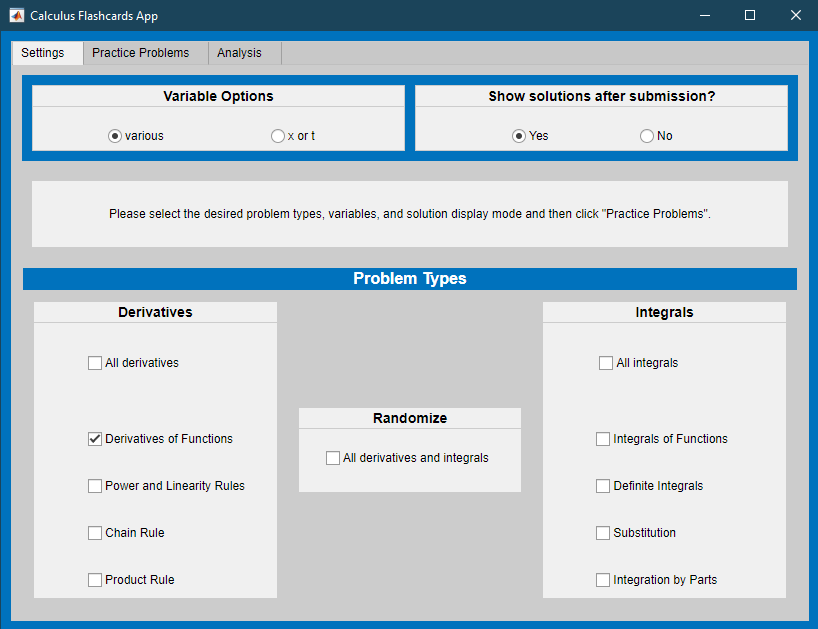](matlab: TarjetasDeCalculo)

 
TarjetasDeCalculo

[⇦ Menú principal](matlab:open('MainMenu.mlx'))

## Funciones auxiliares locales 

Si deseas ver los detalles del código, selecciona la pestaña** View **y cambia a **Output inline**. Como alternativa, selecciona **Output inline** usando el ícono   en la parte superior derecha del panel Live Editor. 

** Practicar funciones de generación de problemas **

 Construir un problema para mostrar 

function [myFun,varChoice,bds] = GenProbType(varOpts)
% genProbType configura una variable y genera una función aleatoria
%
% Entradas: varOpts es una matriz de posibles variables
% Salidas: myFun es una función simbólica
% varChoice es la variable independiente
% [a, b] son los límites de la integral definida, si requerido

% Seleccione aleatoriamente una variable del conjunto varOpts
varChoice = varOpts(randi([1 length(varOpts)],1));

% Utilice genFunDiff para generar funciones simples
% genFunDiff se define en Funciones auxiliares
% Las entradas a genFunDiff son la variable varChoice, un rango de valores
% entre los cuales seleccionar coeficientes y un valor que indica cuál Las advertencias
% ya se han impreso durante la generación del problema.
        syms f(x) x 
        [f(x),~] = GenFunDiff([1 10],x,[1 10],0);
        myFun = f(varChoice);
        bds = randi([-3,4],[1 2]);
        a = bds(1); %#ok<NASGU>
        b = bds(2); %#ok<NASGU>
        % Mostrar el problema integral
        disp("Calculate the integral:")
        displayFormula("F(varChoice) == int(myFun,varChoice,a,b)")
end

 Generar funciones aleatorias apropiadas 

function [myFunc,type] = GenFunDiff(bds,var,range,prevFuncType)
syms f(t)                    % Crear una función simbólica f(t)
params = randi(bds,[1 4]);   % Elija aleatoriamente los valores de los parámetros
shift = randi([0 max(abs(bds))],1); % Elija aleatoriamente un turno que puede ser 0
sgns = randi([0 1],[1 3]);   % Elija aleatoriamente signos +/-
type = randi(range,1);


% Para facilitar la lectura, cree los parámetros a,b,c yd.
a = (-1)^sgns(1)*params(1);
b = (-1)^sgns(2)*params(2);
c = max(params(3),params(4));  % c > 0, solo se usa como denominador
d = (-1)^sgns(3)*shift;

switch type
    case 1
        f(t) = a*t^b+c*t^d;
    case 2
        f(t) = a*t^b+t^(d/c);
    case 3
        f(t) = t^a+c*t^b+t^d;
    case 4
        f(t) = t^a+c*t^b+d;
    case 5
        f(t) = a*t^(b);
    case 6
        f(t) = a*t^(b/c);
    case 7
        f(t) = a*log(abs(b)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")
        end
    case 8
        f(t) = a*exp(b*t);
        if prevFuncType ~= 8
        disp("Recuerda que exp(x) es la notación para e^x en MATLAB.")
        end
    case 9
        f(t) = a*sin(b*t);
    case 10
        f(t) = a*cos(b*t);
    case 11
        f(t) = a*log(ceil(c/4)*t);
        if (prevFuncType ~= 7)&&(prevFuncType ~= 11)
            disp("Recuerda que log(x) es la notación " + ...
                "para un logaritmo natural en MATLAB.")
        end
    case 12
        f(t) = a*t^c;
    case 13
        f(t) = a*sin(b*t+d)*exp(b*t);
    case 14
        f(t) = a*cos(b*t+d)*exp(b*t);
end
myFunc = f(var);
end

 Manejar envíos 

function [lastFive,errorCount,totAttempts,adjustCount] = ResubmissionCheck(totAttempts,totProbs, ...
    adjustCount,myFun,varChoice,bds,myAnswer,errorCount,lastFive)
if sum(totAttempts > (totProbs + adjustCount))
    % Check if this is a resubmission after the solution has been provided
    % If so, provide feedback but do not record in errorCount or lastFive
    % If not, update the values of lastFive and errorCount using check1
    adjustCount = totAttempts-totProbs;
   [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);

elseif sum(totAttempts < (totProbs + adjustCount))
    % Check if this is a submission after the generation of multiple problems that were skipped
    % If so, add the skipped problems to errorCount and adjust the totAttempts
    % to compensate. Explain to the user that skipped problems count as incorrect.
    numSkipped = totProbs + adjustCount - totAttempts;
    errorCount = errorCount + numSkipped;
    totAttempts = totProbs + adjustCount;
    for k = 1:length(totProbs)
        if numSkipped(k) < 5
            lastFive(k,:) = [lastFive(k,1+numSkipped:5),zeros(1,numSkipped)];
        else
            lastFive(k,:) = zeros(1,5);
        end
        if sum(numSkipped) > 1
        disp("Los "+sum(numSkipped)+" problemas generados sin intentos de solución " + ...
            "han sido incluidos en el conteo de errores.")
        disp(" ")
    elseif sum(numSkipped) == 1
        disp("El problema generado sin un intento de solución ha sido " + ...
            "incluido en el conteo de errores.")
        end
        [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
    end
else
        [lastFive,errorCount] = Check1(myFun,varChoice,bds,myAnswer,errorCount,lastFive);
end
end

 Verificar que la solución enviada sea correcta 

function [lastFive,errorCount] = Check1(myFunc,myVar,bds,myAnswer,errorCount,lastFive)
% check1 genera respuestas correctas integrando y actualizando
% errorCount y lastFive
%
% Entradas: myFunc es la función simbólica para diferenciar 
% o integrar myVar es la variable independiente myAnswer es 
% la función o número de prueba simbólico errorCount es un número 
% entero que rastrea el total de intentos incorrectos *-- -* 
% lastFive es un vector que rastrea los últimos cinco intentos 
% Salida: correctAnswer es una función simbólica que es la solución 
% a probType aplicada a myFunc(myVar) con bds
tol = 1e-3;
correctAnswer = int(myFunc,myVar,bds);
if isequal(myAnswer,str2sym("DNE"))
    myAnswer = nan;
end
lastFive(1:4) = lastFive(2:5);
disp("Cuando se simplifica, esta función es: ")
disp(myAnswer)
if correctAnswer == myAnswer
    disp("Esa respuesta es correcta.")
    lastFive(5) = 1;
elseif isnan(correctAnswer) && isnan(myAnswer)
    disp("Esa respuesta es correcta. Esta integral no existe.")
    lastFive(5) = 1;
elseif isinf(correctAnswer) && isinf(myAnswer)
    if sign(real(correctAnswer))==sign(myAnswer)
        disp("Esa respuesta es correcta. La integral diverge hacia:")
        disp(correctAnswer)
        lastFive(5) = 1;
    else
        disp("Tienes razón en que la integral diverge, pero no en la dirección.")
        disp("La integral diverge hacia: ")
        disp(correctAnswer)
        lastFive(5) = 0;
    end
elseif ~isreal(myAnswer)
    disp("Tu respuesta debería ser un número real finito. Por favor, inténtalo de nuevo.")
elseif abs(double(myAnswer-correctAnswer))<tol
    disp("Esa respuesta está redondeada. Un valor más preciso es:")
    disp(correctAnswer)
    lastFive(5) = 1;
else
    disp("Eso es incorrecto. Recuerda ser preciso. La respuesta correcta es:");
    a = bds(1); %#ok<NASGU>
    b = bds(2); %#ok<NASGU>
    displayFormula("int(myFunc,myVar,a,b)==correctAnswer")
    % respuesta correcta %#ok<NOPRT>
    errorCount = errorCount + 1;
    disp("Por favor, inténtalo de nuevo con un nuevo problema.")
    lastFive(5) = 0;
end
end

 Analizar los resultados y dar retroalimentación 

function AnalyzeResults(totProbs,errorCount,totAttempts,adjustCount,lastFive)
% analiceResults proporciona retroalimentación en el caso de un solo tipo de problema
% totProbs, errorCount, totAttempts y ajustaCount son números enteros
% lastFive es un vector
overallRight = (1 - sum(errorCount)/sum(totProbs))*100;
if sum(totAttempts) > sum(totProbs)
    % Si el usuario ha vuelto a enviar después de ver la solución, responda
    disp("¿Por qué estás reenviando después de saber la solución?")
    disp("Los reenvíos no se incluyen en tus estadísticas.")
    if sum(adjustCount) > 1
        % Si el usuario está reenviando repetidamente, anímalo a usar
        % este generador de problemas como se pretende, comenzando de nuevo
        disp("Has reenviado " + sum(adjustCount) + " veces.")
        disp("Por favor, considera reiniciar el conteo usando el botón `Inicializar Valores'.")
    end
end
if totProbs >= 5
    lastCorrect = sum(lastFive);
    % If more than 5 problems have been attempted, provide grammatically
    % appropriate feedback on success rates
    if lastCorrect > 1
str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, %i fueron correctos.",overallRight,totProbs,lastCorrect);
    elseif lastCorrect == 1
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, uno fue correcto.",overallRight,totProbs);
    elseif lastCorrect == 0
        str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
            "De los últimos cinco, ninguno fue correcto.",overallRight,totProbs);
    end
else
    % Si se han intentado menos de 5 problemas, fomente la perseverancia.
    str = compose("La tasa de éxito general es %.1f%% en %i problemas totales \n\n" + ...
        "Por favor, haz al menos cinco problemas.",overallRight,totProbs);
end
disp(str)
end